## Controls Systems Textbook Example 10.6

### Reset matlab environment

clearvars
close all
clc
s = tf('s');

### Specs: $\zeta=0.707,\ K_v\ge20$


$$L(s)=G_C(s)G(s)=\frac{K}{s(s+10)^2}$$


G = 1 / (s * (s + 10)^2);   % type 1

### Design of a phase-lag compensator


$$K_{v}=\frac{K}{10^2}=20\Rightarrow K=2000$$


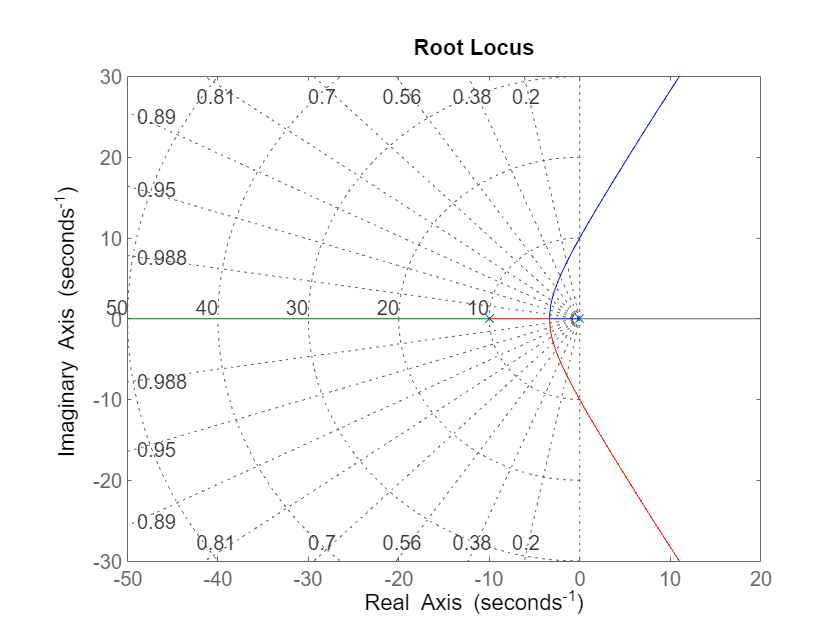

rlocus(G), sgrid


$$\text{But for the original root locus, } K\approx243\text{ when }\zeta=0.707.\\
\Rightarrow\ \alpha=\frac{z}{p}=\frac{2000}{243}\approx8.23\Rightarrow\text{choose }z=0.01,\ \alpha=9$$


K = 243;
z = 0.01;
G_C = (s + z) / (s + z/9);
T = feedback(K * G_C * G, 1);
damp(T)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.17e-01                 1.00e+00       2.17e-01         4.62e+00    
 -2.84e+00 + 2.80e+00i     7.13e-01       3.99e+00         3.52e-01    
 -2.84e+00 - 2.80e+00i     7.13e-01       3.99e+00         3.52e-01    
 -1.41e+01                 1.00e+00       1.41e+01         7.08e-02    


K_V = evalfr(s * K * G_C * G, 10^-10)

K_V = 21.8700